ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);

load occupancy_map.mat
Map = occupancyMap(Map);

sv.Map = Map

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: Inf


sv.ValidationDistance = 0.01

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: 0.0100


ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];


planner = plannerRRT(ss,sv,MaxConnectionDistance=2);


start = [40 70 0];
goal = [180 30 0];

rng(100, 'twister');
[pathObj, solvInf] = plan(planner, start, goal)

pathObj =   navPath with properties:

      StateSpace: [1×1 stateSpaceSE2]
          States: [111×3 double]
       NumStates: 111
    MaxNumStates: Inf


solvInf = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 1517
    NumIterations: 2303
         TreeData: [4553×3 double]


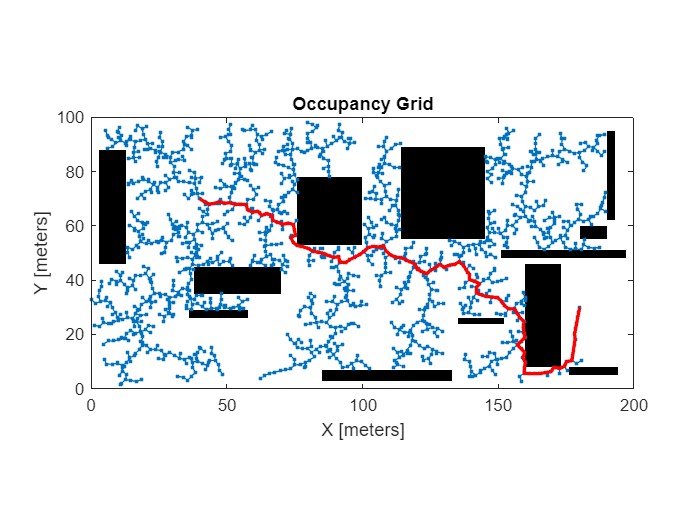



show(Map)
hold on
% Tree expansion
plot(solvInf.TreeData(:,1),solvInf.TreeData(:,2),'.-')
% Draw path
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2)